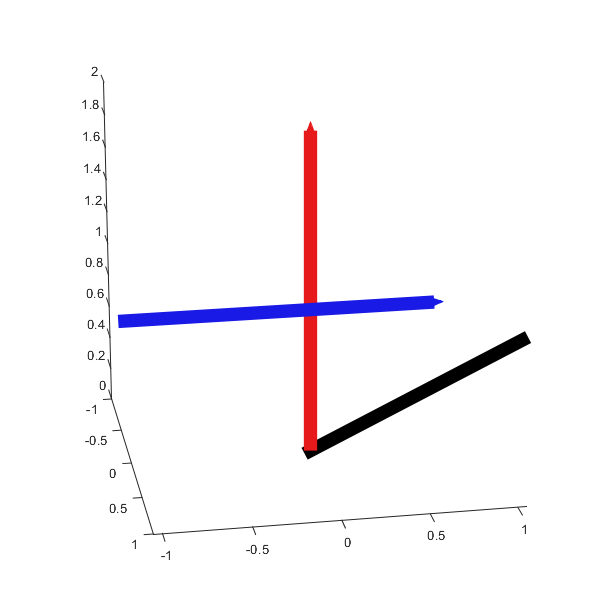

h_fig = figure(1);
clf
set(h_fig,'Visible','on')
set(h_fig, "Position", [1487 408 600 600])
set(h_fig,'color','w');
camproj('perspective')
axis equal off
axis on

view(80,20)
hold on



update_list = {
    diagrams.arrow([-1;-1;0.5], [-1; 1; 0.5], 'color', diagrams.colors.blue, 'LineWidth', 10)
    diagrams.arrow([0;0;0],[0;0;2], 'color', diagrams.colors.red, 'LineWidth', 10)
};

h_3d = plot3([0 1], [0 1], [0 1], 'k', LineWidth=10);

uistack(update_list{end}.an, 'bottom')
%uistack(h_3d, 'top')

diagrams.runall(update_list)

hold off
set(h_fig,'KeyPressFcn',@(~,~)diagrams.runall(update_list));
set(h_fig, 'renderer', 'painters')